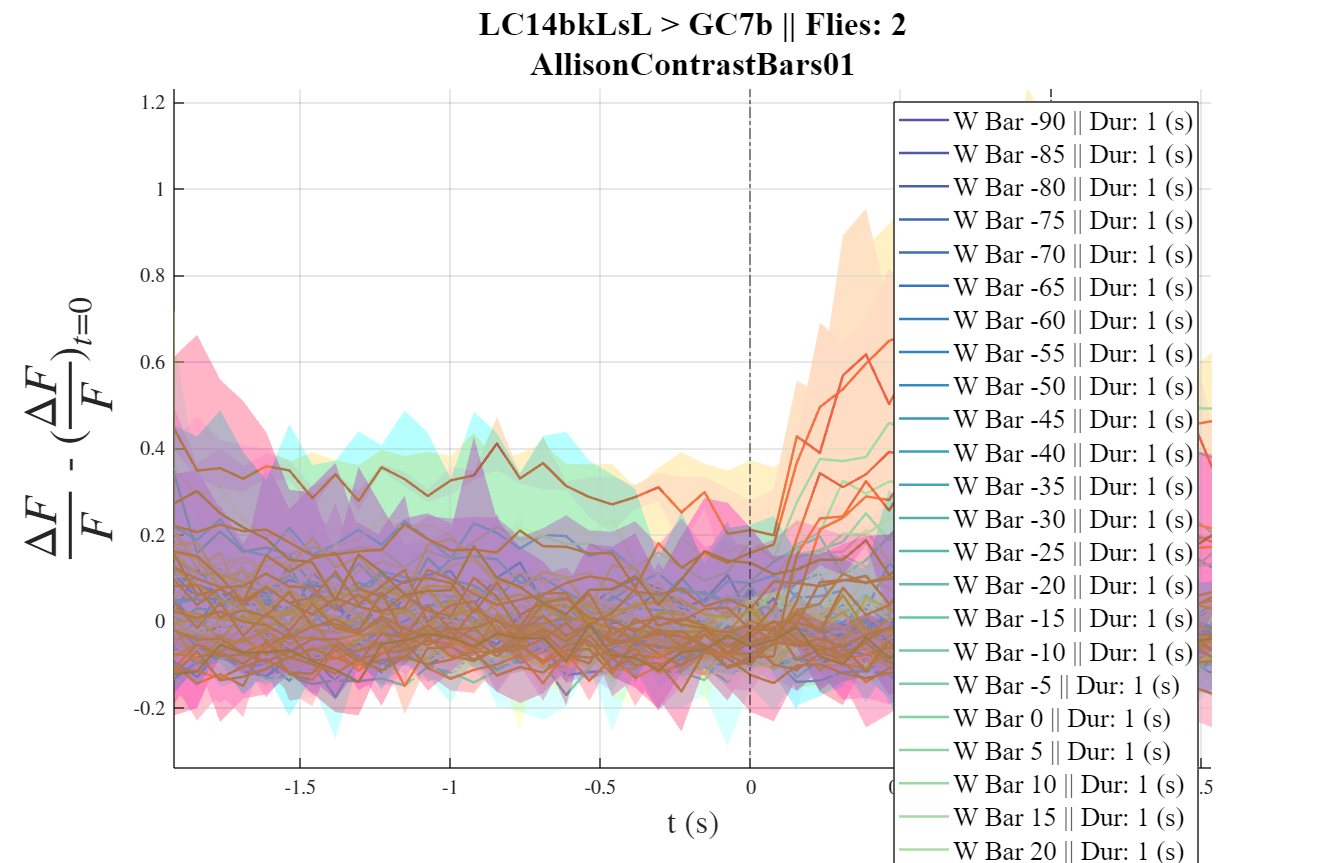

% AllisonContrastBars Imaging Analysis (P5)
% I. Pull workspace from G:/
% II. Imaging Analysis Plots
%    -> See TOC below
% III. Recording? ----- To Do ***

%% Ia. Directory Dialog Box
% OPTION (a) Select a specifc workspace.mat from directory - good for
% making new plots for data that has already been analyzed.
% *** Note: For opt. (a) you must MANUALLY SAVE figures.
% OPTION (b) Automatically select folder and the code will only analyze new
% workspace.mat files.
clc; clearvars; close all;
zz = 1; % test this should change for multiple data files 10.31.23
promptAns2 = iA_wsDirP5();
%% ---------------------------------------------------------------------------------------------------------------------------------------
%% --- OPTION (a) --- Select a specific workspace.mat from directory - good for troubleshooting/ creating new plots
%% ---------------------------------------------------------------------------------------------------------------------------------------
if isempty(promptAns2)
    % Select from directory
    disp('Select a Workspace.m file using the file explorer:');
    [file, path] = uigetfile(['G:\.shortcut-targets-by-id\14uKDX4lMhjd5bJ4DSGt4R7i5XHY2c-V7\The Clark Lab\Workspaces\P5\','.mat'], 'Select a .mat file in G:/');
    wsFileName = fullfile(path, file);
    load(wsFileName);
    if file == 0 % Escape prompt
        disp('File selection canceled.');
        return;
    else % Workspace was loaded
        promptAns2{1,1} = 'P5'; % needed for future code - why? 10.03.23
        wsDir = fullfile(path, file);
        disp([wsDir, ' was selected.']);
    end
    param.stim = stim;
    % TEMP: DELETE WHEN WORKSPACES ARE OLDER THAN 10.04.23
    param.sensor = sensor;
    param.cellType = cellType;

    savePathFigs = ['G:\.shortcut-targets-by-id\14uKDX4lMhjd5bJ4DSGt4R7i5XHY2c-V7\The Clark Lab\Completed Analysis\Psycho5 CA\', cellType,'\'];
    %% II. Plot Figures [Table of Contents]
    % Fig. 01 Resp & SEM Plot for N Flies
    % Fig. 02 vsweep15_480 Subplots with pos in x-axis
    % Fig. 03 AllisonContrastBars01 Plot with pos in x-axis
    % Fig. 04 WaveFlashBarObjectLoom_x20y-20_3rep t Subplots
    % Fig. 05sweepingFullBars_4D_5reps x & y pos Subplots
    [Fig_01] = genRespSEMv2(exp, info, param);

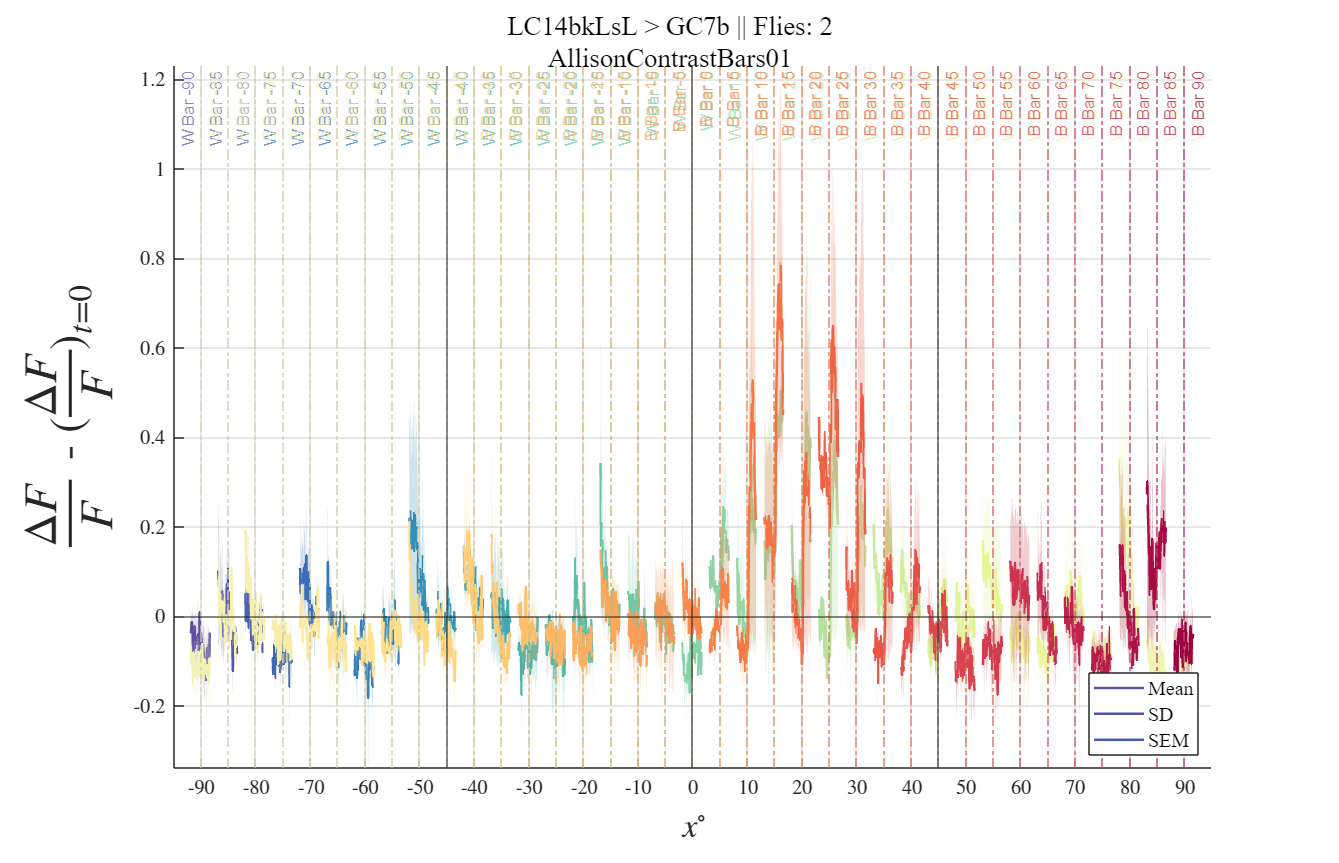

    [Fig_03, Fig_03b, Fig03c] = ContrastBars01(exp, info, param);

    %% Table of total number of flies, flyIDs, recording frequency, and recording numbers
    % Is this table legit? Does it show the datapath of ALL in
    % existence or just the selected ones from the workspace 10.17.23
    % damn there is something up with this, maybe make it so it will
    % show ALL the data...figure out wassup
    % ~- temp - delete, new datasets later than 10.17.23 will have this
    param.fliesTot = unique(param.flyID);
    % ~- delete above
    if ~zz
        figTable = sprintf('%s%s%sFtable_%g',cellType,sensor,stim,param.Nrecs);
    else
        figTable = sprintf('%s%s%sFtable_%g',cellType,sensor,stim,param.Nrecs(zz));
    end
    pngFileFT = fullfile(savePathFigs, [figTable, '.png']);
    if ~isfile(pngFileFT)
        flyIDandRecInfo = ones(2, length(param.fliesTot));
        flyIDandRecInfo(1,:) = linspace(1, length(param.fliesTot), length(param.fliesTot));
        flyIDandRecInfo(2,:) = param.fliesTot;
        [uniqueValues, ~, idx] = unique(param.flyID);
        freq = histcounts(idx, 1:max(idx)+1);
        flyIDandRecInfo(3,:) = freq;
        flyIDandRecInfo(4,1) = freq(1);
        for tT = 2:length(param.fliesTot)
            flyIDandRecInfo(4,tT) = freq(tT)+flyIDandRecInfo(4,tT-1);
        end
        figure;
        sgtitle({[param.cellType, ' > ', param.sensor],stim},'Interpreter', 'none','FontSize',12)
        uitable('Data', flyIDandRecInfo', 'ColumnName', {'Index', 'FlyIDs', 'fRecs', 'NRecs'},'Position', [135 25 277 340]);
        saveas( gcf,fullfile(savePathFigs, [figTable, '.png']),'png')
        disp('Fly ID Table Saved')
    end
    %% ---------------------------------------------------------------------------------------------------------------------------------------
    %%               --- OPTION (b) --- Automatically select folder and the code will only analyze new workspace.mat files ---
    %% ---------------------------------------------------------------------------------------------------------------------------------------
else
    % Ib. Load in workspace
    wsDir = ['G:\.shortcut-targets-by-id\14uKDX4lMhjd5bJ4DSGt4R7i5XHY2c-V7\The Clark Lab\Workspaces\', char(promptAns2{1,1})];
    disp([char(promptAns2{1,1}), ' was selected.']);
    disp([wsDir, ' was loaded.']);
    % Load list of completed analysis
    completedAnalysis = {};  % Initialize
    P5AnalysisDir = fullfile(wsDir, 'P5wsAnalysis.txt');
    if exist(P5AnalysisDir, 'file')
        completedAnalysis = importdata(P5AnalysisDir);  % Load the list
    end
    disp('List of completed analysis (cAnalysisDir.txt) was loaded.');
    recordings = dir(fullfile(wsDir, '*.mat'));
    % Ic. Loop through dataset
    for zz = 1:length(recordings)
        wsFileName = recordings(zz).name;  % Get the file name
        % Id. Skip any repeats/ ones that have been done before
        % % % if ~ismember(wsFileName, completedAnalysis) % Block this when adding new figs
        wsPath = fullfile(wsDir, wsFileName);
        load(wsPath)

        NrecsStr = num2str(param.Nrecs); % Delete for WS after 01.02.24
        cleanedString = '';
        for nn = 1:length(NrecsStr)
            charValue = double(NrecsStr(nn));
            % Include only printable characters and standard alphanumeric characters
            if isstrprop(NrecsStr(nn), 'alphanum') || isstrprop(NrecsStr(nn), 'print')
                cleanedString = [cleanedString, NrecsStr(nn)];
            end
        end
        param.Nrecs = NrecsStr;
        % -DELETE ABOVE


        % Edit the save path so if the 'cellType' folder doesn't exist one
        % is created ***
        savePathFigs = ['G:\.shortcut-targets-by-id\14uKDX4lMhjd5bJ4DSGt4R7i5XHY2c-V7\The Clark Lab\Completed Analysis\Psycho5 CA\', cellType,'\'];
        %% II. Plot Figures [Table of Contents]
        % Fig. 01 Resp & SEM Plot for N Flies
        % Fig. 02 vsweep15_480 Subplots with pos in x-axis
        % Fig. 03 AllisonContrastBars01 Plot with pos in x-axis
        % Fig. 04 WaveFlashBarObjectLoom_x20y-20_3rep t Subplots
        % Fig. 05 sweepingFullBars_4D_5reps x & y pos Subplots

        % % % % % %% Fig. 01 Resp & SEM Plot for N Flies
        % % % % % % Save Info
        % % % % % [A,B] = size(Nrecs);
        % % % % % if size(B) > 1
        % % % % %     fig01 = sprintf('%s%s%sF1_%g',cellType,sensor,stim,param.Nrecs(size(1,zz)));
        % % % % % else
        % % % % %     fig01 = sprintf('%s%s%sF1_%g',cellType,sensor,stim,'X');
        % % % % % end
        %
        % % % % % fig01 = sprintf('%s%s%sF1_%g',cellType,sensor,stim,param.Nrecs(zz));
        % % % % % pngFileF1 = fullfile(savePathFigs, [fig01, '.png']);
        % % % % % % Plot/ save if file has not been analyzed
        % % % % % if ~isfile(pngFileF1)
        % % % % %     % Plot Function for generic delf f/f t-trace
        % % % % %     [Fig_01] = genRespSEMv2(exp, info, param);
        % % % % %     % Save/ Export
        % % % % %     saveas( gcf,fullfile(savePathFigs, [fig01, '.png']),'png')
        % % % % %     disp('Fig. 01 Saved')
        % % % % % else % Fig. 01 already exists
        % % % % %     disp('---')
        % % % % % end
        

        %% Fig. 03 AllisonContrastBars01 Plot with pos in x-axis -- ** Create subplot of white and black bars
        % The bars don't move in this plot
        if length(stim) == 21
            fig03 = sprintf('%s%s%sF3_%g',cellType,sensor,stim,param.Nrecs(zz));
            pngFileF3 = fullfile(savePathFigs, [fig03, '.png']);
            fig03b = sprintf('%s%s%sF3b_%g',cellType,sensor,stim,param.Nrecs(zz));
            pngFileF3b = fullfile(savePathFigs, [fig03b, '.png']);
            fig03c = sprintf('%s%s%sF3c_%g',cellType,sensor,stim,param.Nrecs(zz));
            pngFileF3c = fullfile(savePathFigs, [fig03c, '.png']);
            % Plot/ save if file has not been analyzed
            if ~isfile(pngFileF3c)
                if ~exist('TimeXs', 'var')
                    [Fig_01] = genRespSEMv2(exp, info, param);
                end
                [Fig_03, Fig_03b, Fig_03c] = ContrastBars01(exp, info, param);
                saveas( Fig_03,fullfile(savePathFigs, [fig03, '.png']),'png')
                saveas( Fig_03b,fullfile(savePathFigs, [fig03b, '.png']),'png')
                saveas( Fig_03c,fullfile(savePathFigs, [fig03c, '.png']),'png')
                disp('Fig. 03 Saved')
            else % Fig. 03 already exists
                disp('-')
            end
        else
            % disp('Skipping Fig.03 since Stim is not AllisonContrastBars01')
            disp('-')
        end
        
        %% Table of total number of flies, flyIDs, recording frequency, and recording numbers
        % Is this table legit? Does it show the datapath of ALL in
        % existence or just the selected ones from the workspace 10.17.23
        % damn there is something up with this, maybe make it so it will
        % show ALL the data...figure out wassup
        % ~- temp - delete, new datasets later than 10.17.23 will have this
        param.fliesTot = unique(param.flyID);
        % ~- delete above

        if size(B) > 1
            figTable = sprintf('%s%s%sFtable_%g',cellType,sensor,stim,param.Nrecs(zz));
        else
            figTable = sprintf('%s%s%sFtable_%g',cellType,sensor,stim,'Z');
        end


        % figTable = sprintf('%s%s%sFtable_%g',cellType,sensor,stim,param.Nrecs(zz));
        pngFileFT = fullfile(savePathFigs, [figTable, '.png']);
        if ~isfile(pngFileFT)
            flyIDandRecInfo = ones(2, length(param.fliesTot));
            flyIDandRecInfo(1,:) = linspace(1, length(param.fliesTot), length(param.fliesTot));
            flyIDandRecInfo(2,:) = param.fliesTot;
            [uniqueValues, ~, idx] = unique(param.flyID);
            freq = histcounts(idx, 1:max(idx)+1);
            flyIDandRecInfo(3,:) = freq;
            flyIDandRecInfo(4,1) = freq(1);
            for tT = 2:length(param.fliesTot)
                flyIDandRecInfo(4,tT) = freq(tT)+flyIDandRecInfo(4,tT-1);
            end
            figure;
            sgtitle({[param.cellType, ' > ', param.sensor],stim},'Interpreter', 'none','FontSize',12)
            uitable('Data', flyIDandRecInfo', 'ColumnName', {'Index', 'FlyIDs', 'fRecs', 'NRecs'},'Position', [135 25 277 340]);
            saveas( gcf,fullfile(savePathFigs, [figTable, '.png']),'png')
            disp('Fly ID Table Saved')
        end
    end
    disp('Analysis Completed.');
end

% test
data = info.analysis{1, 1}.respMatPlot;
errorBars = info.analysis{1, 1}.respMatSemPlot;
TimeXs = info.analysis{1, 1}.timeX / 1000;  % ms to s
nEpochs = length(data(1,:));
colors = linspecer(nEpochs,'sequential');
epochNames = cellstr(exp.param_file(3, 3:end)); % do I want to do this like how I did epochDur instead?
epochProbeDur = [exp.params(:).duration];
epochDur = epochProbeDur(param.interleave_epochs+1:end);

pos0 = [exp.params(:).relativeX];
pos0 = pos0(param.interleave_epochs+1:end);
stimPos = cell(1, length(pos0));
stimEndPos = ones(length(pos0),1);

for jj = 1:length(pos0)
    stimPos{1,jj} = pos0(jj) + TimeXs;
    stimEndPos(jj) = pos0(jj) + (epochDur(jj)/60);
end

meanData = ones(length(pos0),1); meanData2 = ones(length(pos0),1);
sdData = ones(length(pos0),1); sdData2 = ones(length(pos0),1);
semData = ones(length(pos0),1); semData2 = ones(length(pos0),1);

for jj = 1:length(pos0)
    stimPos{1,jj} = pos0(jj) + TimeXs;
    stimEndPos(jj) = pos0(jj) + (epochDur(jj)/60);

    % t = 0 to 1.0 s
    meanData(jj) = mean(data(26:40,jj));
    sdData(jj) = std(data(26:40,jj));
    semData(jj) = std(data(26:40,jj)) ./ sqrt(40-26);

    % t = 0 to end
    meanData2(jj) = mean(data(26:end,jj));
    sdData2(jj) = std(data(26:end,jj));
    semData2(jj) = std(data(26:end,jj)) ./ sqrt(74-26);
end


Fig_03c = figure('Units', 'normalized', 'OuterPosition', [0, 0, 0.65, 1]);
tiles = tiledlayout(3,4,'TileSpacing','Compact'); % ***
% legendLayout.Tile = 'east';

% Subplot 1: ON bars
% % % subplot(3,6,1:6)
nexttile([1 3])
hold on;

% Plot mean with error bars (SD and SEM)
% % % errorbar(pos0(1:37), meanData(1:37), sdData(1:37), '.', 'color', colors(4,:), 'LineWidth', 1.5);
% % % errorbar(pos0(1:37), meanData(1:37), semData(1:37), '.','color', colors(1,:), 'LineWidth', 1.5);
% % % plot(pos0(1:37),meanData(1:37), '-o', 'color', 'm', 'LineWidth', 1.25)
errorbar(pos0(1:37), meanData2(1:37), sdData2(1:37), '.', 'color', colors(8,:), 'LineWidth', 1.5);
errorbar(pos0(1:37), meanData2(1:37), semData2(1:37), '.','color', colors(1,:), 'LineWidth', 1.5);
plot(pos0(1:37), meanData(1:37), '-*', 'color', colors(12,:), 'LineWidth', 1.25)
plot(pos0(1:37), meanData2(1:37), '-o', 'color', 'k', 'LineWidth', 1.25)


xline(0,'-')
xline(-45,'-')
xline(45,'-')
yline(0,'-')

set(gca, 'TickLabelInterpreter', 'latex', 'FontSize', 12);
grid on;
axis tight;
sgtitle({[num2str(param.cellType),' > ',num2str(param.sensor),' || Flies: ', num2str(info.analysis{1,1}.numFlies)], 'RF Map'}, 'FontSize', 16, 'FontName', 'Times New Roman', 'Interpreter', 'none');
title('ON Bars RF Map', 'FontSize', 12, 'FontName', 'Times New Roman', 'Interpreter', 'none');
xlabel('$x^\circ$', 'FontSize', 20, 'Interpreter', 'latex');
xticks(-90:10:90);  % Set the x-ticks from -90 to 90 in increments of 10
xticklabels(-90:10:90);  % Use the same values for x-tick labels
ylabel('$\frac{\Delta F}{F}$ - $(\frac{\Delta F}{F})_{t = 0}$', 'FontSize', 28, 'Interpreter', 'latex');
xlim([-95,95]);

nexttile
legend({'$\sigma$, t = 0 - 1.5 s', 'SEM, t = 0 - 1.5 s', '$\mu$, t = 0 - 1.0 s', '$\mu$, t = 0 - 1.5 s'}, 'Interpreter', 'Latex', 'Location', 'NorthWest', 'FontName', 'Times New Roman', 'FontSize', 12);


% % % Fig_03d = figure('Units', 'normalized', 'OuterPosition', [0, 0, 1, 1]);
% Subplot 2: OFF bars
% % % % subplot(3,6,7:12)
nexttile([1 3])
hold on;

% Plot mean with error bars (SD and SEM)
% % % errorbar(pos0(1:37), meanData(1:37), sdData(1:37), '.', 'color', colors(4,:), 'LineWidth', 1.5);
% % % errorbar(pos0(1:37), meanData(1:37), semData(1:37), '.','color', colors(1,:), 'LineWidth', 1.5);
% % % plot(pos0(1:37),meanData(1:37), '-o', 'color', 'm', 'LineWidth', 1.25)
errorbar(pos0(38:end), meanData2(38:end), sdData2(38:end), '.', 'color', colors(8,:), 'LineWidth', 1.5);
errorbar(pos0(38:end), meanData2(38:end), semData2(38:end), '.','color', colors(1,:), 'LineWidth', 1.5);
plot(pos0(38:end), meanData(38:end), '-*', 'color', colors(12,:), 'LineWidth', 1.25)
plot(pos0(38:end), meanData2(38:end), '-o', 'color', 'k', 'LineWidth', 1.25)


xline(0,'-')
xline(-45,'-')
xline(45,'-')
yline(0,'-')

set(gca, 'TickLabelInterpreter', 'latex', 'FontSize', 12);
grid on;
axis tight;
title('OFF Bars RF Map', 'FontSize', 12, 'FontName', 'Times New Roman', 'Interpreter', 'none');
xlabel('$x^\circ$', 'FontSize', 20, 'Interpreter', 'latex');
xticks(-90:10:90);  % Set the x-ticks from -90 to 90 in increments of 10
xticklabels(-90:10:90);  % Use the same values for x-tick labels
xlim([-95,95]);

nexttile
legend({'$\sigma$, t = 0 - 1.5 s', 'SEM, t = 0 - 1.5 s', '$\mu$, t = 0 - 1.0 s', '$\mu$, t = 0 - 1.5 s'}, 'Interpreter', 'Latex', 'Location', 'NorthWest', 'FontName', 'Times New Roman', 'FontSize', 12);

% 
% % % % % subplot(3,6,13:18)
nexttile([1 3])


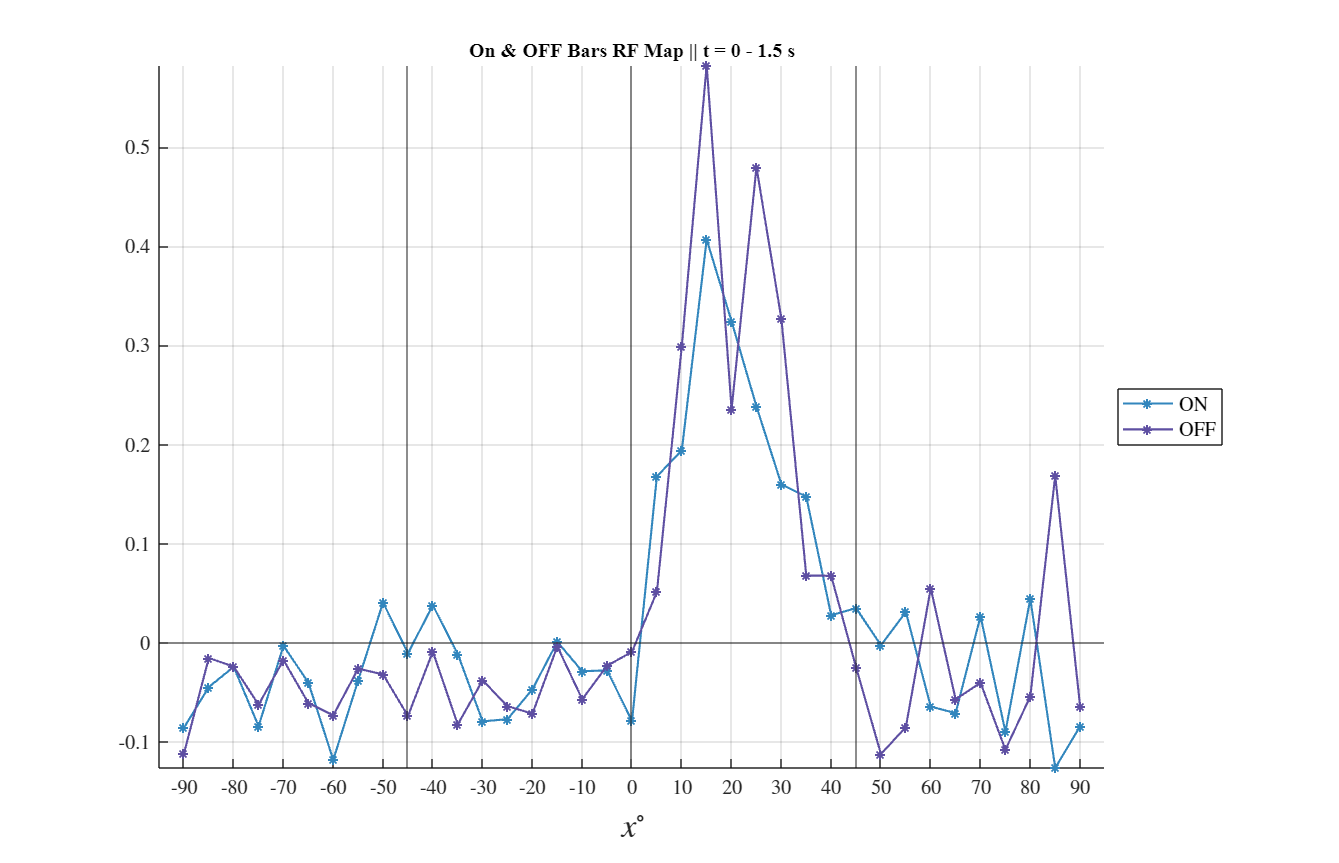

% tiles = tiledlayout(1,4,'TileSpacing','Compact'); % ***
tiles = tiledlayout('flow'); % ***

hold on;

% plot(pos0(1:37), meanData(1:37), ':*', 'color', colors(12,:), 'LineWidth', 1.25)
plot(pos0(1:37), meanData2(1:37), '-*', 'color', colors(8,:), 'LineWidth', 1.25)
% plot(pos0(38:end), meanData(38:end), '-*', 'color', 'k', 'LineWidth', 1.25)
plot(pos0(38:end), meanData2(38:end), '-*', 'color', colors(1,:), 'LineWidth', 1.25)
xline(0,'-')
xline(-45,'-')
xline(45,'-')
yline(0,'-')

set(gca, 'TickLabelInterpreter', 'latex', 'FontSize', 12);
grid on;
axis tight;
title('On & OFF Bars RF Map || t = 0 - 1.5 s', 'FontSize', 12, 'FontName', 'Times New Roman', 'Interpreter', 'none');
xlabel('$x^\circ$', 'FontSize', 20, 'Interpreter', 'latex');
xticks(-90:10:90);  % Set the x-ticks from -90 to 90 in increments of 10
xticklabels(-90:10:90);  % Use the same values for x-tick labels
xlim([-95,95]);

leg = legend({'ON','OFF'}, 'Interpreter', 'Latex', 'Location', 'EastOutside', 'FontName', 'Times New Roman', 'FontSize', 12);

% leg = legend('Orientation', 'Horizontal');
% leg.Layout.Tile = '';

Property assignment is not allowed when the object is empty.  Use subscripted assignment to create an array element.

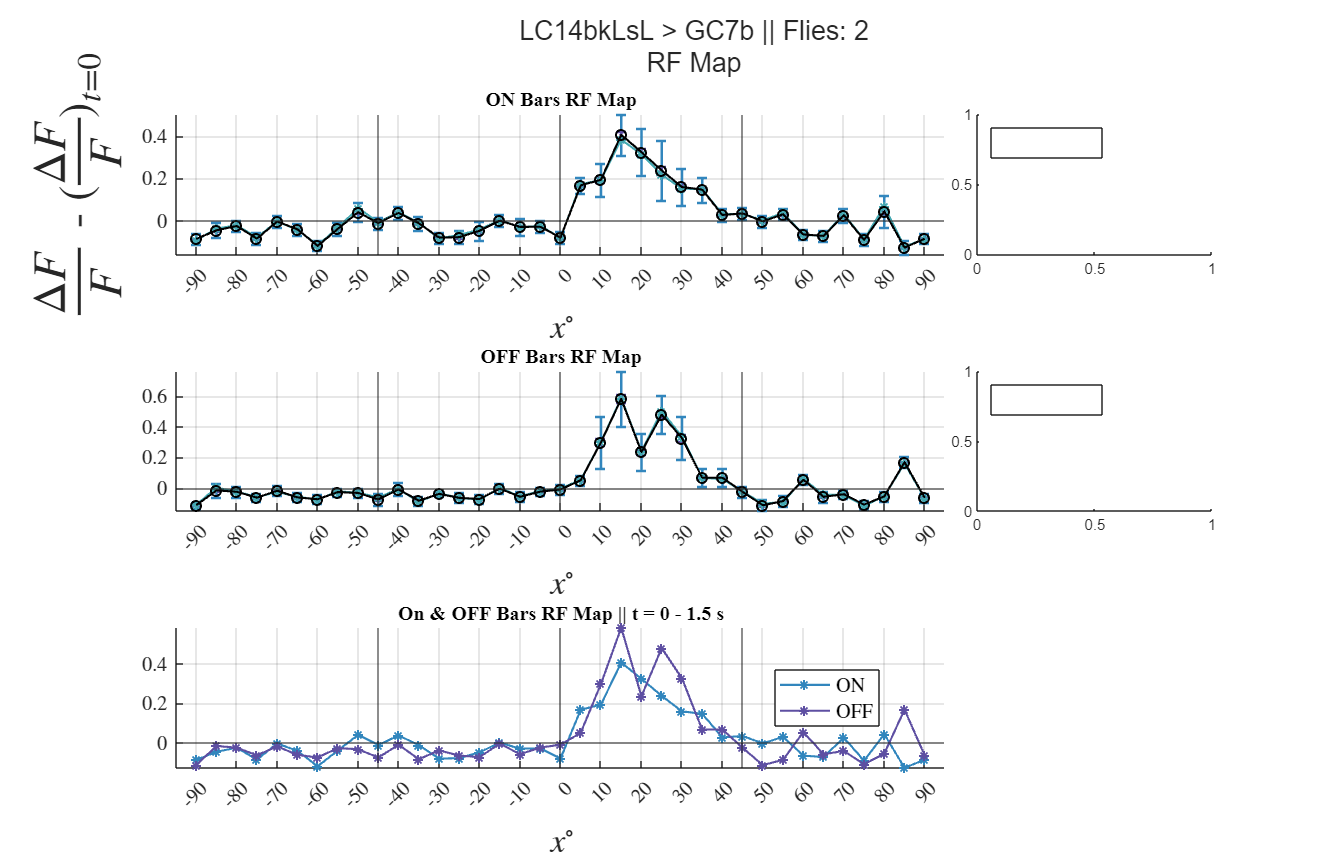

% Remove the legend from the main plot layout
delete(lgd);  % Remove the legend from the main tiled layout